# Ex. 1.

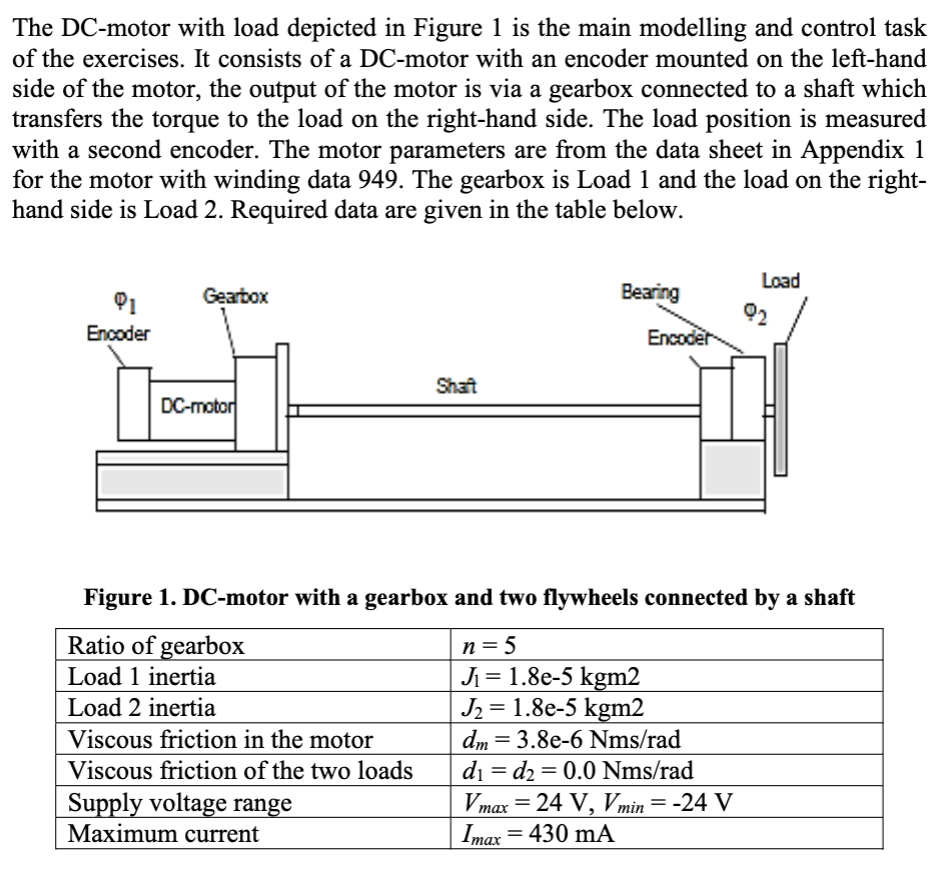

### Definitions

n = 5;
J1 = 1.8 * 1e-5;
J2 = 1.8 * 1e-5;
dm = 3.8 * 1e-6;
Vmax = 24;
Vmin = -24;
Imax = 430 * 1e-3;
R = 112;
Imaxcont = 182 * 1e-3;
noloadrpm = 6440; %rpm
Jmot = 7.46 * 1e-7;
L = 11.4 * 1e-3;
K = 69.7 * 1e-3;

Jtot = J1 + J2 / n^2;

### State space model

The state space model was derived on paper assuming that the shaft is stiff and has zero inertia. 


$$A = \left( \matrix{-\frac{d_m}{J_{mot} + J_{tot}} & \frac{K}{n * (J_{mot} + J_{tot})} \cr -\frac{K * n}{L} & -\frac{R}{L}} \right), \quad
B = \left( \matrix{0 \cr \frac{1}{L}} \right), \quad
C = \left( \matrix{1 & 1} \right), \quad
D = 0, \quad

State\ variables = \left( \matrix{\dot{\varphi}
 \cr I} \right) \quad$$
 

A = [-dm/(Jmot+Jtot), K/(n*(Jmot+Jtot)); -K*n / L, -R/L];

B = [0; 1/L];

C = [1, 1];

D = 0;

sys2 = ss(A, B, C, D);

### Transfer functions

The transfer functions of the system from voltage to load velocity and from voltage to current are derived using the matlab ss2tf function

[num, den] = ss2tf(A, B, [1 0], 0); % Returns tf from voltage to angular velocity
G1 = tf(num, den)


G1 =
 
         6.282e04
  -----------------------
  s^2 + 9825 s + 2.381e04
 
Continuous-time transfer function.
Model Properties


[num, den] = ss2tf(A, B, [0 1], 0); % Returns tf from voltage to current
G2 = tf(num, den)


G2 =
 
      87.72 s + 17.12
  -----------------------
  s^2 + 9825 s + 2.381e04
 
Continuous-time transfer function.
Model Properties


### Poles and zeroes of the transfer functions

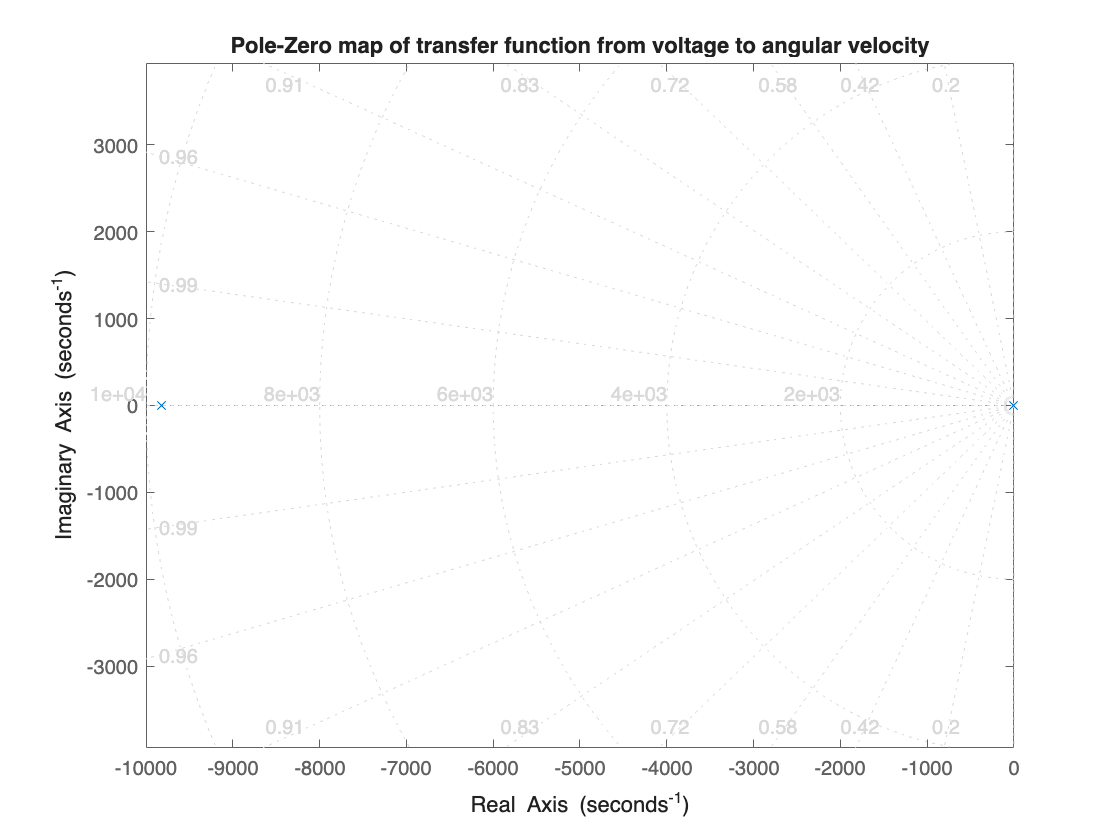

figure;
pzp = pzplot(G1); axis equal; grid on 
title("Pole-Zero map of transfer function from voltage to angular velocity");

poles = pole(G1)

poles = 1.0e+03 *

   -9.8223
   -0.0024


zeroes = tzero(G1)


zeroes =

  0×1 empty double column vector



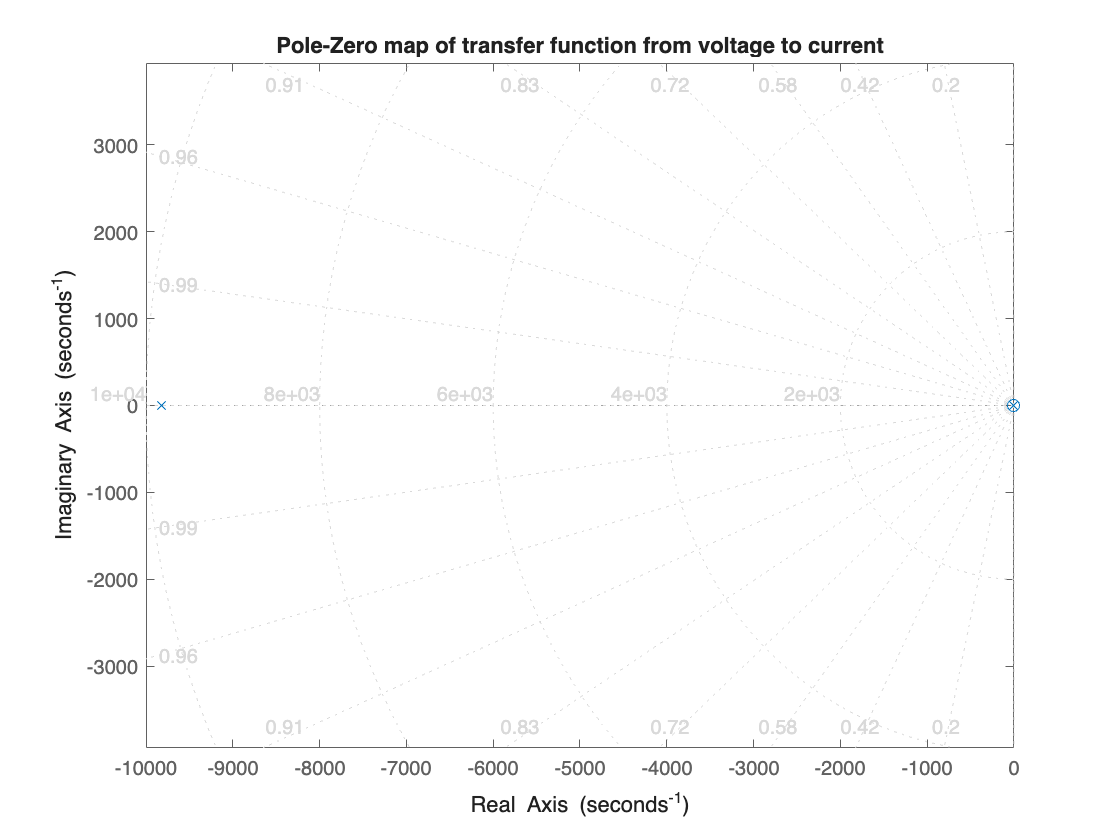

figure;
pzp = pzplot(G2); axis equal; grid on 
title("Pole-Zero map of transfer function from voltage to current");

poles = pole(G2)

poles = 1.0e+03 *

   -9.8223
   -0.0024


zeroes = tzero(G2)

zeroes = -0.1952

There are no poles or zeroes at the origin for either of the two transfer functions.

### Step responses

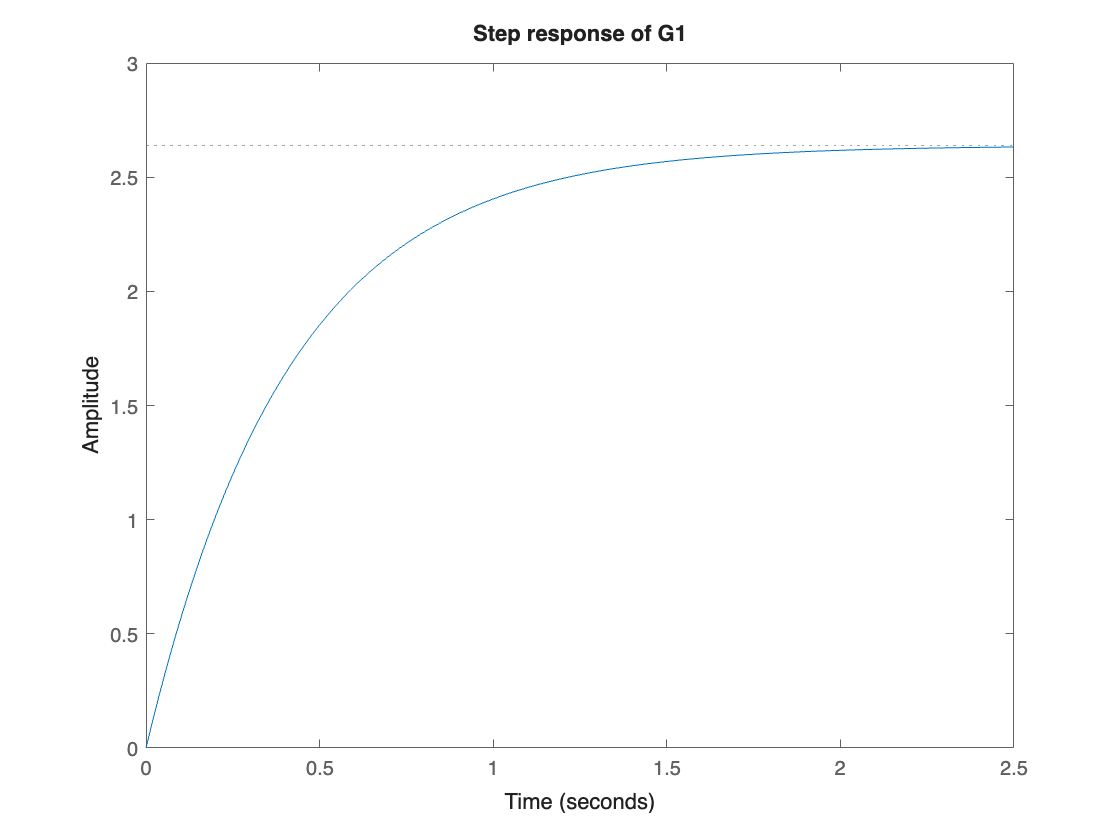

figure;
sp1 = stepplot(G1);
title("Step response of G1");

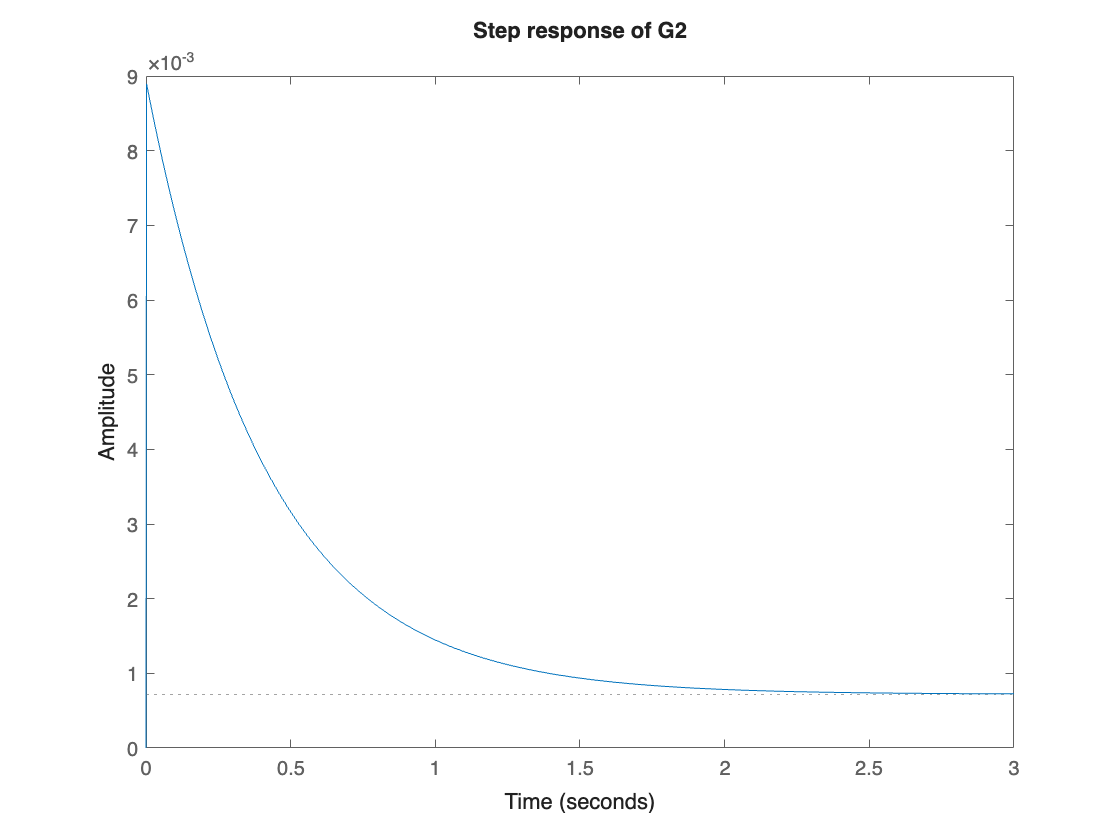


figure;
sp2 = stepplot(G2);
title("Step response of G2");

The initial value of the current step repsonse can be found using the initial value theorem: $Initial \ value = \lim_{s \to \infty} s*G(s)$ which gives that the initial value of the transfer function from voltage to current is $87.72 * 10^{-3}$. 